Vytvoření melspektrogramů + uložení obrázků

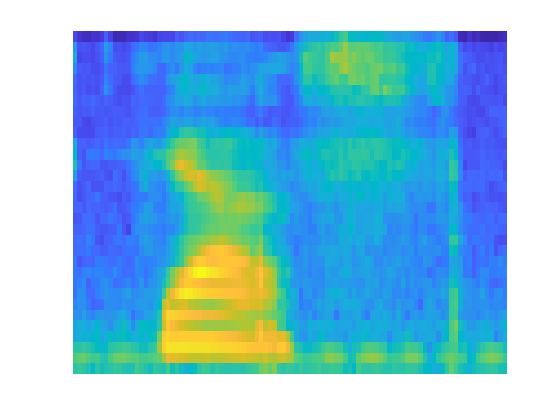

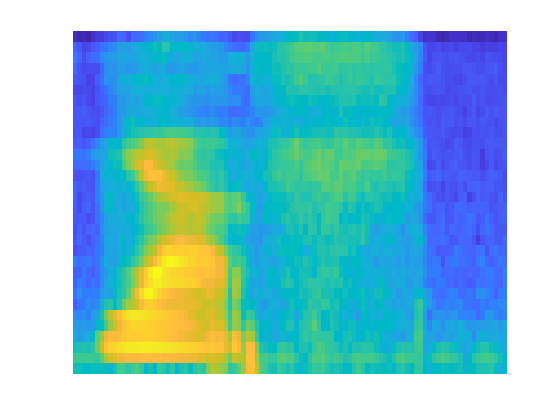

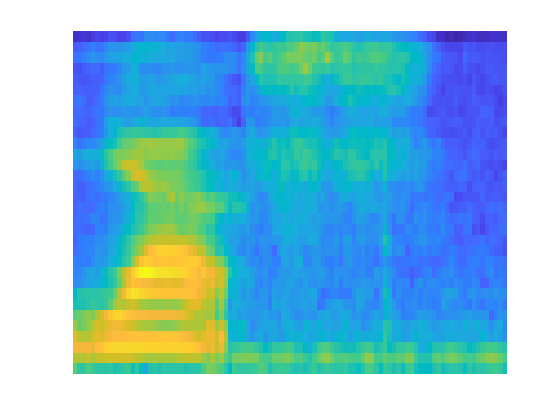

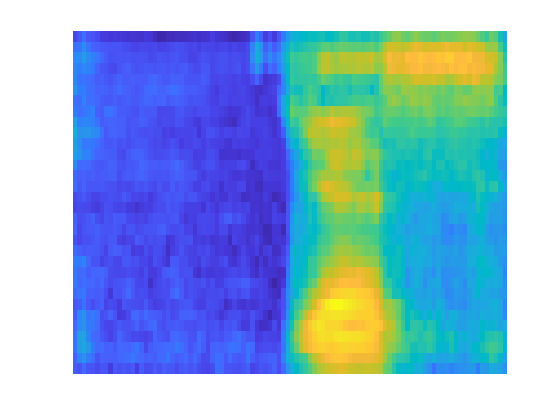

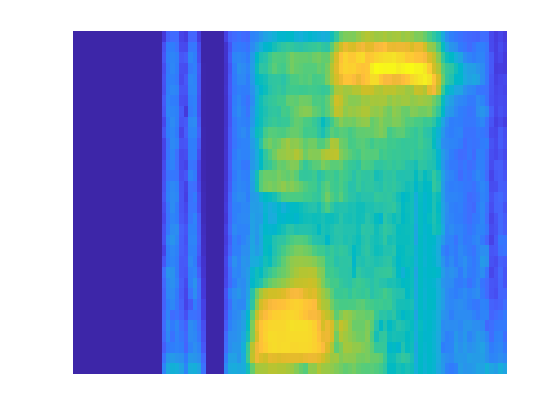

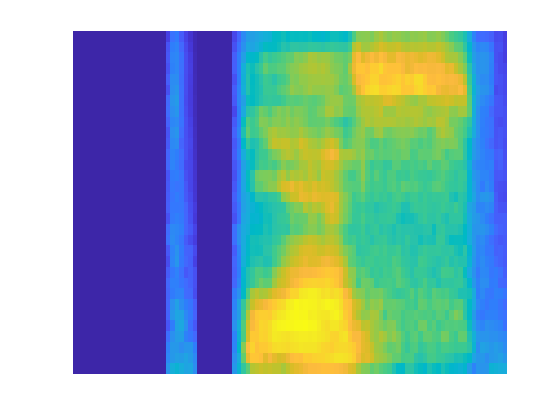

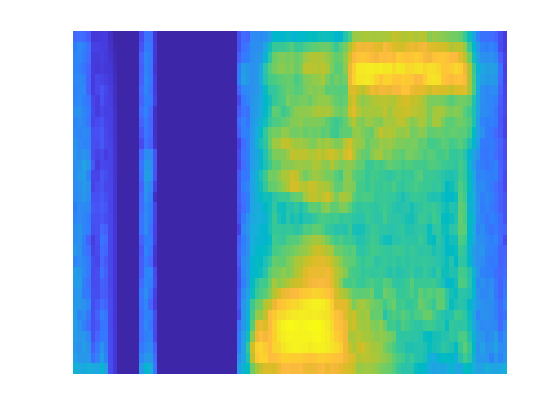

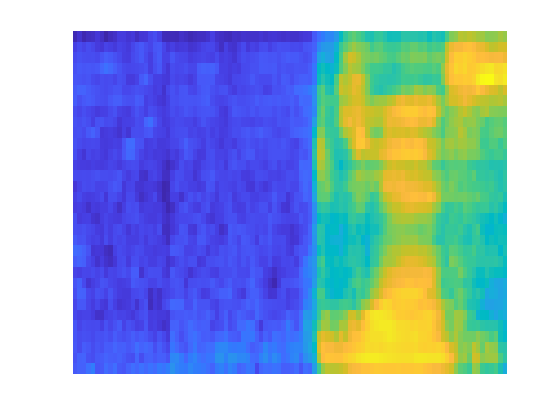

clear

folder='C:\Users\hrusk\Desktop\VŠ\5-semestr\ZOD\hruskovicova-projekt\smallDataset\yes';
subfolder = 'C:\Users\hrusk\Desktop\VŠ\5-semestr\ZOD\hruskovicova-projekt\smallDataSetImg\yes';
audio_files = dir(fullfile(folder,'*.wav'));

for i = 1:numel(audio_files)
    filename=audio_files(i).name;
    [data,Fs] = audioread(fullfile(folder,filename));
    AudioData{i}=data(:,1);
    f = figure;
    melSpectrogram(AudioData{i}, Fs);
    set(gca, 'Visible', 'off');
    colorbar('off');
    audio_files(i).name = audio_files(i).name(1:end-4);
    saveas(f, fullfile(subfolder, audio_files(i).name + ".png"));
end

Vytvoření obrázkové databáze

imageDatasetPath = fullfile('smallDataSetImg');
imds = imageDatastore(imageDatasetPath, 'IncludeSubfolders', true, 'LabelSource','foldernames');

Rozdělení dat (test, valid, train)

[imdsTrain,imdsValidation] = splitEachLabel(imds, 0.7, 'randomize');
[imdsValidation, imdsTest] = splitEachLabel(imdsValidation, 0.5, 'randomized');

nastavení CNN

I = imread('smallDataSetImg\down\0a7c2a8d_nohash_0.png');
imagesize = size(I);

numClasses = countEachLabel(imdsTrain);
numClasses = height(numClasses);

layers = [
    imageInputLayer(imagesize)
    convolution2dLayer(8,20,'Padding',"same")
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer

%     convolution2dLayer(3,12,'Padding', 'same')
%     batchNormalizationLayer
%     reluLayer
%     
%     maxPooling2dLayer(3,'Stride',2,'Padding',"same")
%     
%     convolution2dLayer(3,2*12,'Padding',"same")
%     batchNormalizationLayer
%     reluLayer
%     
%     maxPooling2dLayer(3,'Stride',2,'Padding',"same")
%     
%     convolution2dLayer(3,4*12,'Padding',"same")
%     batchNormalizationLayer
%     reluLayer
%     
%     maxPooling2dLayer(3,'Stride',2,'Padding',"same")
%     
%     convolution2dLayer(3,4*12,'Padding',"same")
%     batchNormalizationLayer
%     reluLayer
%     
%     convolution2dLayer(3,4*12,'Padding',"same")
%     batchNormalizationLayer
%     reluLayer
%     
%     maxPooling2dLayer([1 13])
% 
%     fullyConnectedLayer(numClasses)
%     softmaxLayer
%     classificationLayer
];

options = trainingOptions('sgdm', ...
    'MaxEpochs',5, ...
    'Shuffle',"every-epoch",...
    "Plots",'training-progress',...
    "Verbose",false,...
    'ValidationData',imdsValidation);

trénování CNN

net = trainNetwork(imdsTrain, layers, options);

Pred = classify(net, imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = sum(Pred == YValidation)/numel(YValidation)

test = classify(net, imdsTest);